gscatter(metrics(:,1), metrics(:,2), players,'rgb','osd');
xlabel('Goals');
ylabel('Assists');
N = size(metrics,1);
lda1 = fitcdiscr(metrics(:,1:2),players);
ldaClass = resubPredict(lda1);
ldaResubErr = resubLoss(lda1);
[ldaResubCM_s,grpOrder_s] = confusionmat(players,ldaClass)

ldaResubCM_s =      8     0     3
     1     5     2
     3     3     5


grpOrder_s = 3×1 cell array
    {'Terry'   }
    {'Ferreira'}
    {'Cole'    }


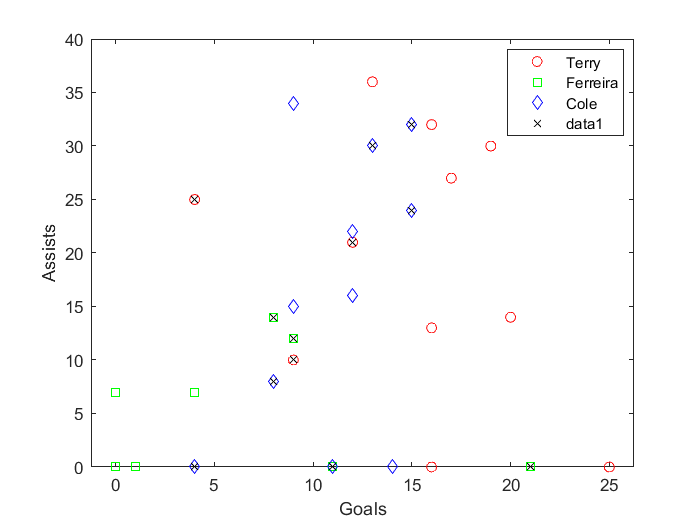

bad = ~strcmp(ldaClass,players);
hold on;
plot(metrics(bad,1), metrics(bad,2), 'kx');
hold off;

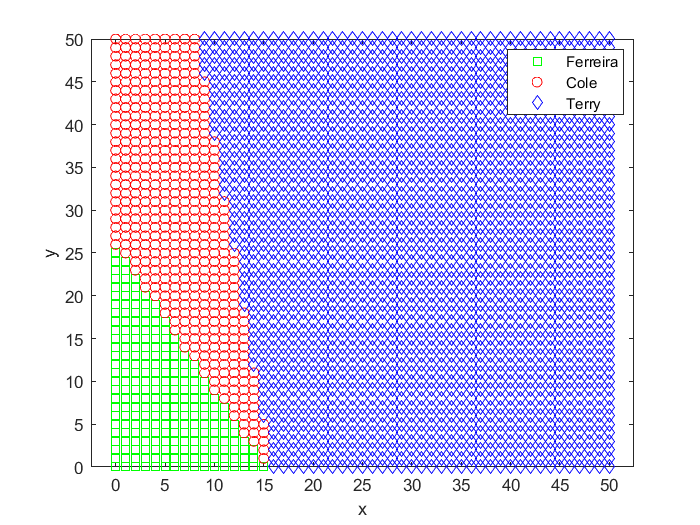

[x,y] = meshgrid(0:50,0:50);
x = x(:);
y = y(:);
j = classify([x y],metrics(:,1:2),players);
gscatter(x,y,j,'grb','sod')